clc;
clear;
close all;

% ====== 使用者設定 ======
samples = 5120;  % 每幀取樣點數（依 Acquisition 設定）
filePath = fullfile('C:\Users\sgrc - 325\Desktop\git\das\get\das_data', ...
                    '2025-10-31_15-43-29.bin');
smoothWindow = 100;  % 平滑視窗長度
% ========================

% 確認檔案存在
if exist(filePath, 'file') ~= 2
    error('❌ 找不到檔案：%s', filePath);
end

% 開啟檔案
fileID = fopen(filePath, 'rb');
if fileID == -1
    error('⚠️ 無法開啟檔案：%s', filePath);
end

% 取得檔案大小（bytes）
fseek(fileID, 0, 'eof');
fileSize = ftell(fileID);
frewind(fileID);

% 計算共有幾幀資料
bytesPerSample = 2;  % int16 = 2 bytes
frameCount = floor(fileSize / (samples * bytesPerSample));

fprintf('📄 檔案大小 = %.2f MB\n', fileSize/1e6);

📄 檔案大小 = 58.37 MB


fprintf('🧩 每幀 %d 點，共 %d 幀\n', samples, frameCount);

🧩 每幀 5120 點，共 5700 幀


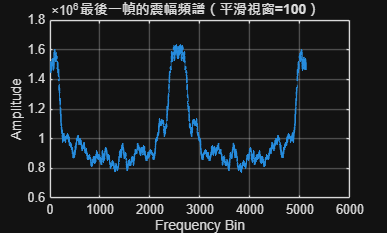


% ====== 只讀取最後一幀 ======
% 跳到最後一幀起始位置
offset = (frameCount - 1) * samples * bytesPerSample;
fseek(fileID, offset, 'bof');

% 讀取最後一幀資料
data_raw = fread(fileID, [samples, 1], 'int16=>double');
fclose(fileID);

% ====== 計算頻域資料 ======
N = length(data_raw);
data_fft = fft(data_raw);

% 取震幅與相位角
amplitude = abs(data_fft);
phase = angle(data_fft);

% ====== 平滑處理（每100筆平均） ======
amplitude_smooth = smoothdata(amplitude, 'movmean', smoothWindow);
phase_smooth = smoothdata(phase, 'movmean', 1);

% ====== 繪圖 ======

% 1️⃣ 震幅頻譜
figure;
plot(amplitude_smooth, 'LineWidth', 1.2);
xlabel('Frequency Bin');
ylabel('Amplitude');
title(sprintf('最後一幀的震幅頻譜（平滑視窗=%d）', smoothWindow));
grid on;

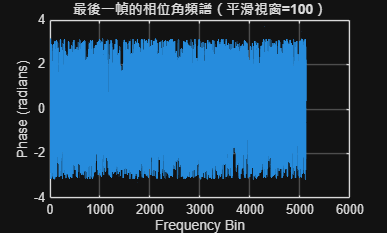


% 2️⃣ 相位角頻譜
figure;
plot(phase_smooth, 'LineWidth', 1.2);
xlabel('Frequency Bin');
ylabel('Phase (radians)');
title(sprintf('最後一幀的相位角頻譜（平滑視窗=%d）', smoothWindow));
grid on;


fprintf('✅ 已讀取最後一幀並繪製平滑後的震幅與相位。\n');

✅ 已讀取最後一幀並繪製平滑後的震幅與相位。
